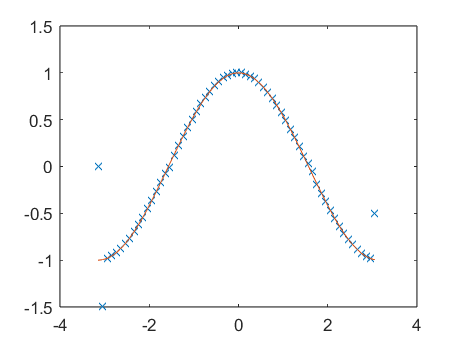

% 测试差分方法
clear;clc;
fd = @(x,dx) GVC2(x,dx);
x = -pi:0.1:pi;
u = [sin(x);cos(x)];
v = [cos(x);-sin(x)];
u_x = fd(u,0.1);
plot(x,reshape(u_x(1,:),1,[]),'x',x,reshape(v(1,:),1,[]))

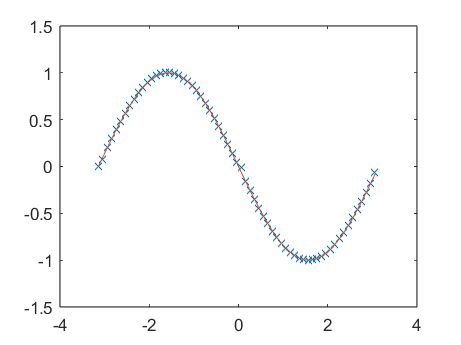

plot(x,reshape(u_x(2,:),1,[]),'x',x,reshape(v(2,:),1,[]))

计算第100步


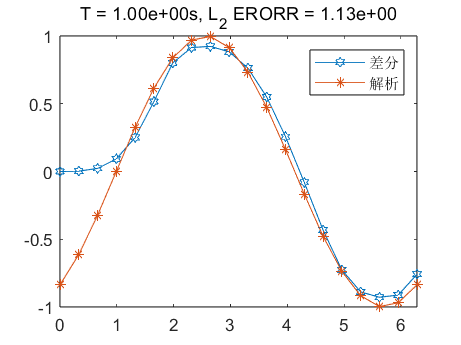

% 测试 RK
s_x = 0;
e_x = 2*pi;
n = 20; % 网格点数量
x = linspace(s_x, e_x, n);
t = 0;
h = 0.01;% 时间间隔
u = sin(x); % u_0

d_x = (e_x - s_x) / n; % 空间间隔

T(1) = t;
L_2_eorr(1) = 0;

% 测试差分
% plot(x, u_x(u, d_x))

k = 1;
% 三阶rungge kutta
rk = RK;
Q = @(u,dx) -GVC2(u,dx);
while t <= 1
    k = k + 1;
    if mod(k,100) == 0
        fprintf('计算第%d步\n',k);
    end

    u = rk.rk3(u,Q,h,d_x);
    
    u_e = sin(x-t);
    t = t + h;
    l_2_error = norm(u_e - u);
    plot(x,u,'-h',x,u_e,'-*')
    ylim([-1 1])
    xlim([s_x e_x])
    title(sprintf('T = %.2ds, L_2 ERORR = %.2d',t,l_2_error))
    legend('差分','解析');
    pause(0.1)

end

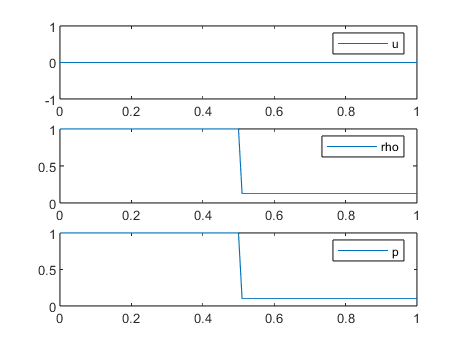

clear;clc;
dt = 0.01;
rk = RK;
fvs = FVS;
sod = MySod(0.01,0,1,dt,5/3);
sod.build(0,1,1,0,0.125,0.1);
sod.show();

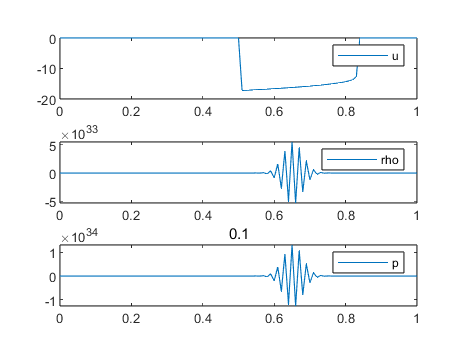


for i = 0:dt:0.1
    sod.timeStep(fvs, rk);
    sod.show();
    title(i)
    pause(0.1);
end